# APMA 2501 - Programming in R & MATLAB: MATLAB Unit 2

## Applying Logic and Conditionals

- Topic 1: Day of the Week Calculator

- Topic 2: Classifying Cubic Functions

- Topic 3: Binary Arithmetic

- Topic 4: Symbolic Computations in MATLAB

## MATLAB Copilot Topic #1: Copilot Chat

MATLAB Copilot Chat is the chat panel inside MATLAB that lets you *talk to* MATLAB Copilot (MathWorks’ built-in AI assistant) to get help writing, modifying, and understanding MATLAB code. You can ask MATLAB Copilot for code snippets, functions, or entire solutions. MATLAB Copilot responses are based on MathWorks documentation and code examples.

% Example


Key tips for using Copilot Chat effectively:

- Break big tasks into small, focused chunks.

- Always ask for test cases after each chunk.

- Provide clear context and specifics—the more precise your input, the better Copilot Chat can help.

- If the conversation starts looping or producing nonsense, clear chat history and start over.

### **Getting User Input**

We’ve seen what happens when we try to input a non-number using `input(...)`

input('Enter a Number: ')

We need to specify that the user input should be treated as a string, without evaluating expressions.

input('Enter a Number: ', 's') % 's' specifies a string input

This lets us do even more testing on the input. However, in our homework platform **MATLAB Grader**, that input format isn’t supported, so we will just assign the values directly in the code.

### Testing User Input

Treating the inputs as strings makes certain tests much easier.

length('314')
length(314)

After performing all string tests, convert input to a number

str2num('12')
str2num('twelve') % Ask Copilot Chat why this gives a blank!

**Question**: How can we use the result of `str2num` to test whether the input "a" was reasonable as a number? (e.g., 19a6 -> not valid)

a = input('Enter a Number: ', 's');

***Copilot Chat prompt:*** "Write an `if/elseif` statement that uses `length(str2num(a))` to check whether the user’s input can be converted into a number. If it converts to exactly one number, display 'Good'; if it converts to nothing (invalid input like `19a6`), display 'No good'. Keep the code short".

% Your code for determining the a is a accepted numeric input.


Do you think the code given by your Copilot Chat works?

## Topic 1: Day of the Week Calculator

Now that we’ve converted to a number, we can do the more familiar tests.

            ***Calender page for 2026***

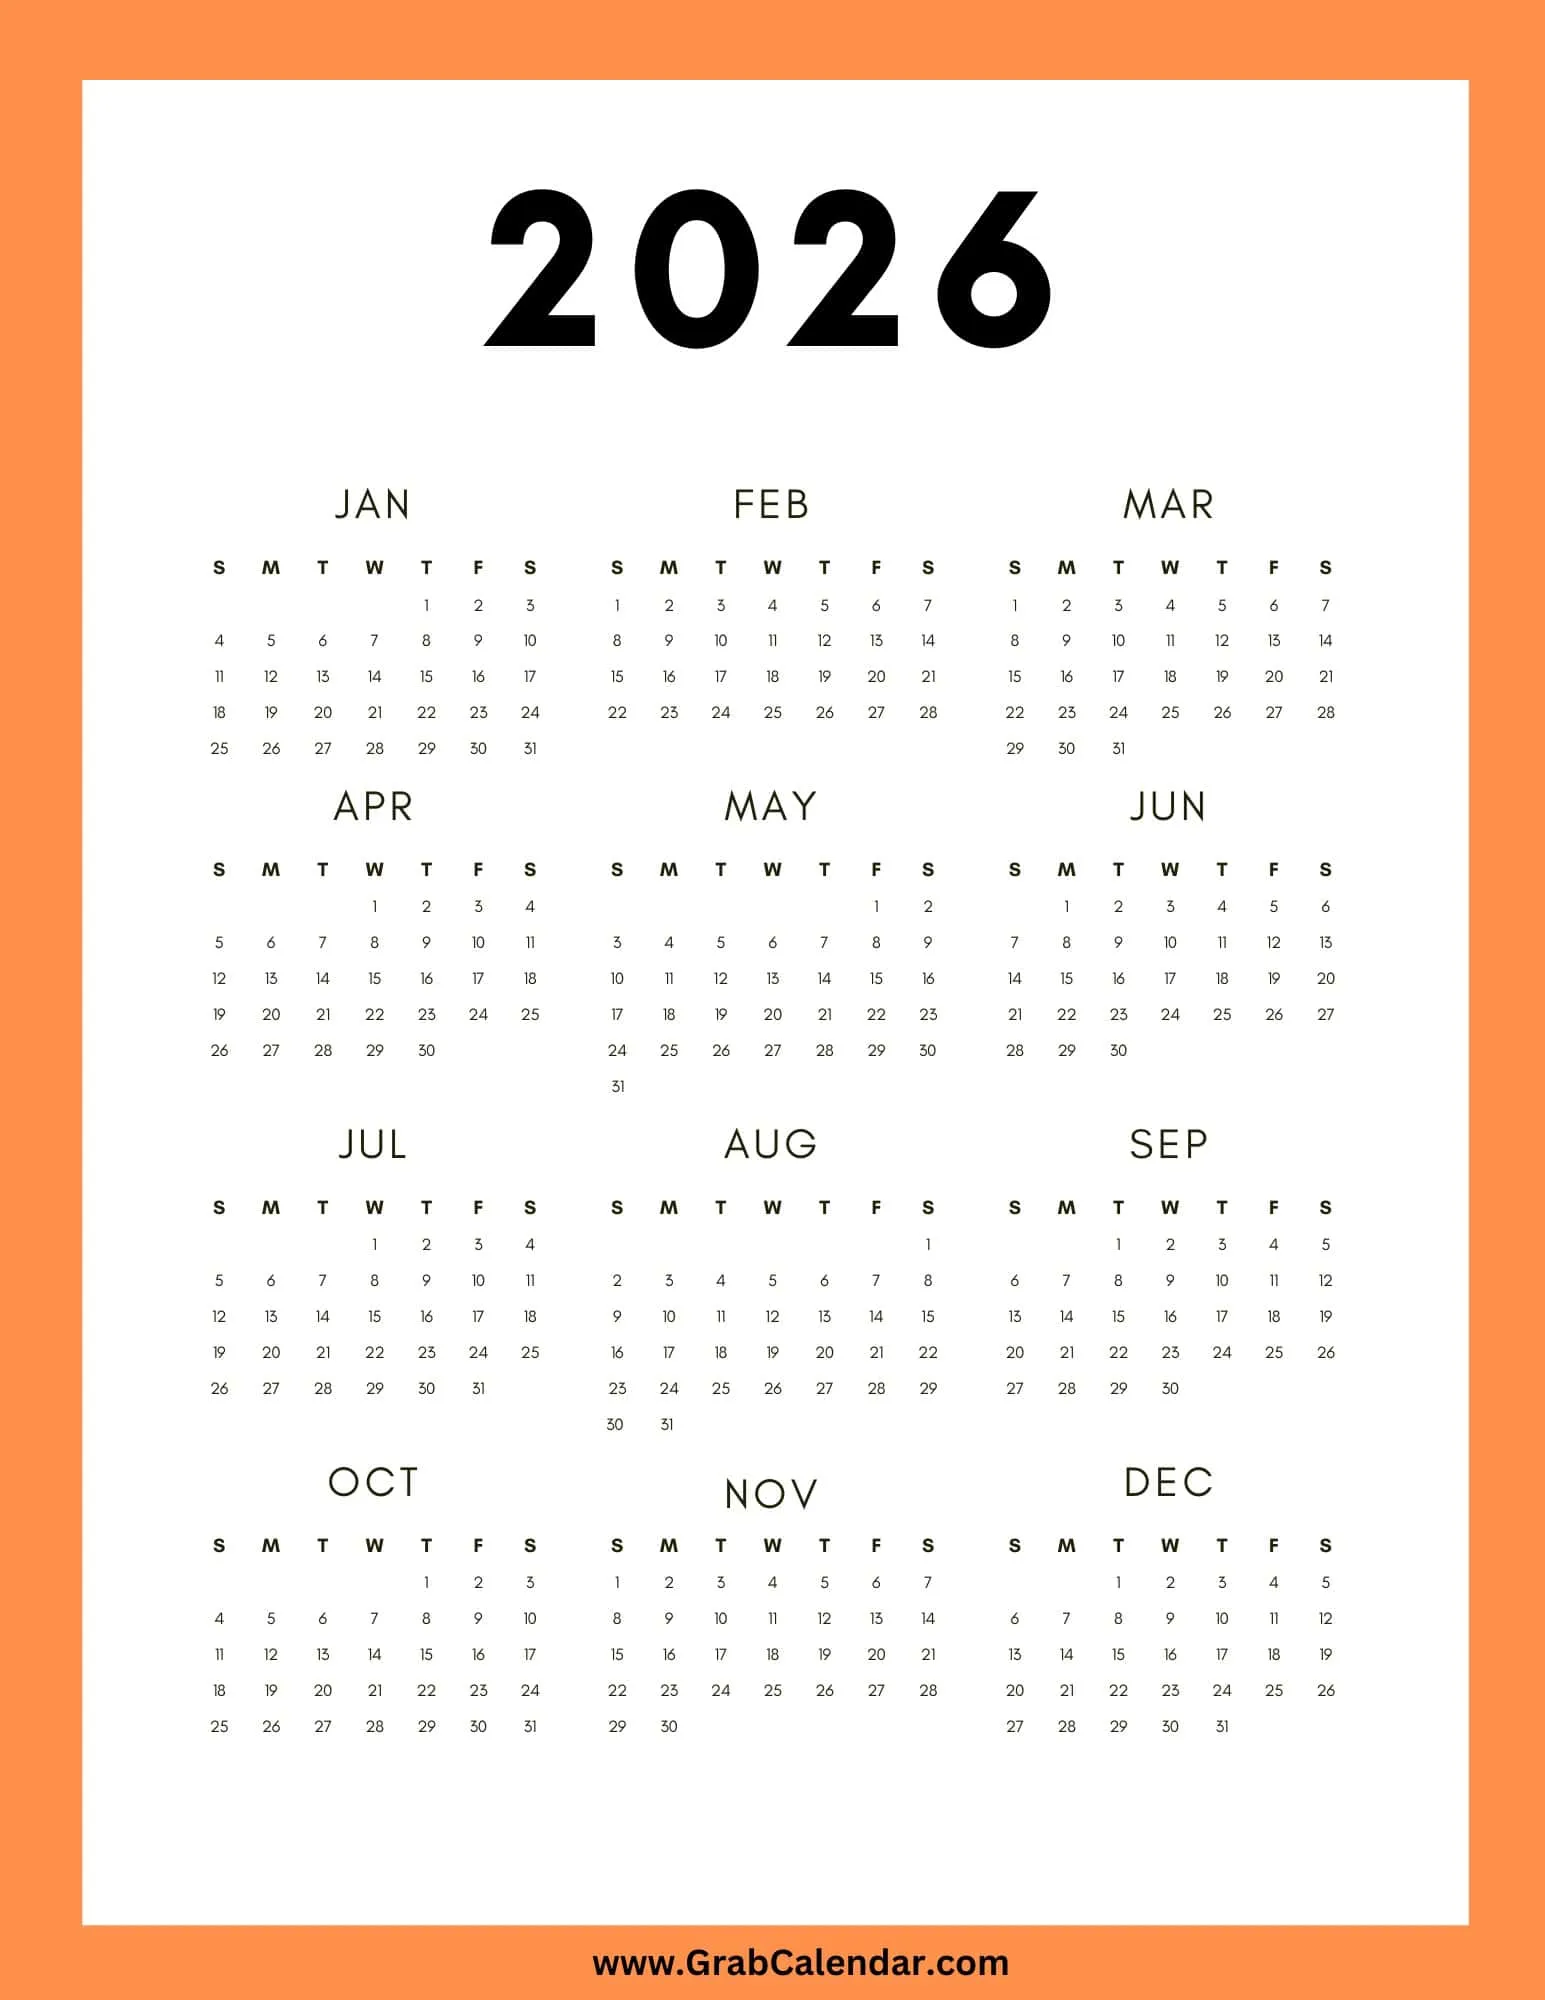

- The year must be an integer in the range [1, 9999]

- The day must be an integer in the range [1, 31]

What if the user inputs June 31st?

### How to Validate the Day?

We know that the day can never be >31, but how do we refine our test based on what the input month is? And how does the leap year change this?

So `max_days` is dependent not only on the month, but also the year (in February)!

#### The `switch` conditional

We could assign max_days with a large if-elseif block, but there’s a cleaner option. A switch statement executes one set of statements from several choices, based on the value of a single variable. Each choice is called a case.

% SWITCH switch_expression
%     CASE case_expr_1
%         Execute code for case 1
%     CASE case_expr_2
%         Execute code for case 2
%     CASE case_expr_3
%         Execute code for case 3
%     OTHERWISE
%         Execute code when no case matches
% END SWITCH

The switch statement compares the value of `switch_expression` with each case expression. If it matches `case_expr_1`, the code for case 1 is executed; if it matches `case_expr_2`, the code for case 2 is executed, and so on. Only the first matching case is executed. If none of the cases match, the code under `otherwise` is executed. The `end` statement marks the end of the switch structure.

#### A `switch` example

% Input a value for x.
x = input('Enter a number: ');
% Start switch block, making decisions based on x.
switch (x)
    case -1 % Note: we don’t write x == -1 as we would with an if statement.
        fprintf('Negative one.\n');
    case 0
        fprintf('Zero.\n');
    case 1
        fprintf('Positive one.\n');
    otherwise
        fprintf('Other value.\n');
end

Feel free to ask Copilot Chat for more `switch` examples. For instance, the sign function takes a number and returns -1 if it’s negative, 0 if it’s exactly zero, and 1 if it’s positive. Can you quickly write a sign function in MATLAB using a `switch` statement?

% Your code for a sign function using switch


#### Leap year

Question: Is it a leap year? (Does Copilot Chat know leap years?)

Answer: A leap year is defined as a year that is either

- Divisible by 4 and not divisible by 100, or

- Divisible by 400

yr = 2024;
is_leapyear = ((mod(yr,4)==0)&&(mod(yr,100)~=0))||(mod(yr,400)==0)

yr = 2023;
is_leapyear = ((mod(yr,4)==0)&&(mod(yr,100)~=0))||(mod(yr,400)==0)

yr = 1900;
is_leapyear = ((mod(yr,4)==0)&&(mod(yr,100)~=0))||(mod(yr,400)==0)

yr = 2000;
is_leapyear = ((mod(yr,4)==0)&&(mod(yr,100)~=0))||(mod(yr,400)==0)

#### Calculation

Once everything is error checked and converted, we can plug in to the day-of-the-week calculation.


$$w=\left(d+\left\lfloor 2\ldotp 6m-0\ldotp 2\right\rfloor +y+\left\lfloor \frac{y}{4}\right\rfloor +\left\lfloor \frac{c}{4}-2c\right\rfloor \right)\;\mathrm{mod}\;7$$


where $w$ is the day of the week (0 is Sunday, …, 6 is Saturday),

$d$ is day of the month,

$m$ is shifted month, `((input_month + 9) mod 12) + 1`,

$y$ is last two digits of year,

$c$ is first two digits of year.

### Day-of-the-week pseudocode

% Get user inputs for DD, MMM, YYYY (e.g., 22, SEP, 2025)

% Perform basic error checks

% “Convert” MMM input to a number (e.g., ‘JUN’ to 6) and set max_days

% Perform calendar-aware error check (e.g., no JUN 31)

% Use equation to calculate w

% Print the day of the week to the screen

## Topic 2: Classifying Cubic Functions

Example: The quadratic equation.

Let’s apply what we’ve learned so far on testing the roots of the quadratic equation, i.e., ${a\;x}^2 +b\;x+c=0$.

Are the roots (1) real and distinct, (2) real and identical, or (3) complex? The well-known roots of this equation are $x=\frac{-b\pm \sqrt{b^2 -4\;a\;c}}{2\;a}$.

The discriminant, $b^2 -4\;a\;c$, determines the behavior of the roots:

- If $b^2 -4\;a\;c<0$, roots are complex

- If $b^2 -4\;a\;c=0$, roots are real and identical

- Otherwise, roots are real and distinct

### Classifying-quadratic-function Pseudocode

% discrim <- b^2 - 4*a*c (Note: the arrow here only means "assign the result to variable discrim")

% if (discrim < 0)
%     write message that equation has two complex roots
% elseif (discrim == 0)
%     write message that equation has two identical real roots
% else
%     write message that equation has two distinct real roots
% end

Is Copilot Chat capable of completing this function using the pseudocode given above?

If we want to classify the shape of a cubic function, the corresponding quadratic (its derivative) is key, because it tells us where the cubic increases, decreases, and changes direction.

## Topic 3: Binary Arithmetic

Numbers are represented in **binary format** in a computer. For example, consider the number $x=124=1\times {10}^2 +2\times {10}^1 +4\times {10}^0$.


$$\begin{array}{rcl}
124 &=& 2 \times 62 + 0\\
62  &=& 2 \times 31 + 0\\
31  &=& 2 \times 15 + 1\\
15  &=& 2 \times 7 + 1\\
7   &=& 2 \times 3 + 1\\
3   &=& 2 \times 1 + 1\\
1   &=& 2 \times 0 + 1
\end{array}
\qquad
(124)_{10}=(1111100)_2$$
                                         
$$\begin{array}{rl}
x =& 1111100\\
x =& 1\times 2^6+1\times 2^5+1\times 2^4+1\times 2^3\\
  & +1\times 2^2+0\times 2^1+0\times 2^0\\
  =& 64+32+16+8+4+0+0=124
\end{array}$$


Q: How does a computer add numbers? A: Using a logic circuit that combines the **AND** and **XOR** gates. (Feel free to ask Copilot Chat for them!)

So how does a computer add numbers? Let's take a look at another example:


$$\begin{array}{rcrclcr}
\text{carry-over bits}\rightarrow
& & 100110 & & & & \\
& & 100110 & = & 32+4+2 & = & 38\\
& + & 100111 & = & 32+4+2+1 & = & +\,39\\
\hline
\text{sum bits}\rightarrow
& & 1001101 & = & 64+8+4+1 & = & 77
\end{array}$$


## Symbolic Computations in MATLAB

**Symbolic Math Toolbox™ **helps to perform symbolic computations. Functions are called using the familiar MATLAB syntax. This toolbox is available for integration, differentiation, simplification, equation solving, and other mathematical tasks. Examples see [Perform Symbolic Computations](https://www.mathworks.com/help/symbolic/performing-symbolic-computations.html).

### **Differentiate Symbolic Expressions**

**Expressions with One Variable**

To differentiate a symbolic expression, use the `diff` command. The following example illustrates how to take a first derivative of a symbolic expression:

syms x
f = sin(x)^2;
diff(f)

**Partial Derivatives**

For multivariable expressions, you can specify the differentiation variable. If you do not specify any variable, MATLAB® chooses a default variable by its proximity to the letter `x`:

syms x y
f = sin(x)^2 + cos(y)^2;
diff(f)

To differentiate the symbolic expression `f` with respect to a variable `y`, enter:

syms x y
f = sin(x)^2 + cos(y)^2;
diff(f, y)

### **Integrate Symbolic Expressions**

**Indefinite Integrals of One-Variable Expressions**

Suppose you want to integrate a symbolic expression. The first step is to create the symbolic expression:

syms x
f = sin(x)^2;
int(f)

**Indefinite Integrals of Multivariable Expressions**

If the expression depends on multiple symbolic variables, you can designate a variable of integration. If you do not specify any variable, MATLAB chooses a default variable by the proximity to the letter `x`:

syms x y n
f = x^n + y^n;
int(f)

**Definite Integrals**

To find a definite integral, pass the limits of integration as the final two arguments of the `int` function:

syms x y n
f = x^n + y^n;
int(f, 1, 10)

### **Solve Equations**

**Solve Algebraic Equations with One Symbolic Variable**

Use the double equal sign (==) to define an equation. Then you can [`solve`](https://www.mathworks.com/help/releases/R2025b/symbolic/sym.solve.html) the equation by calling the solve function. For example, solve this equation:

syms x
solve(x^3 - 6*x^2 == 6 - 11*x)

**Solve Algebraic Equations with Several Symbolic Variables**

If an equation contains several symbolic variables, you can specify a variable for which this equation should be solved. For example, solve this multivariable equation with respect to `y`:

syms x y
solve(6*x^2 - 6*x^2*y + x*y^2 - x*y + y^3 - y^2 == 0, y)

**Solve Systems of Algebraic Equations**

You also can solve systems of equations. For example:

syms x y z
[x, y, z] = solve(z == 4*x, x == y, z == x^2 + y^2)

### **Simplify Symbolic Expressions**

Symbolic Math Toolbox provides a set of simplification functions allowing you to manipulate the output of a symbolic expression. For example, the following polynomial of the golden ratio `phi`

phi = (1 + sqrt(sym(5)))/2;
f = phi^2 - phi - 1
simplify(f)

For example, to show the order of a polynomial or symbolically differentiate or integrate a polynomial, use the standard polynomial form with all the parentheses multiplied out and all the similar terms summed up. To rewrite a polynomial in the standard form, use the `expand` function:

syms x
f = (x ^2- 1)*(x^4 + x^3 + x^2 + x + 1)*(x^4 - x^3 + x^2 - x + 1);
expand(f)

The `factor` simplification function shows the polynomial roots. If a polynomial cannot be factored over the rational numbers, the output of the `factor` function is the standard polynomial form. For example, to factor the third-order polynomial, enter:

syms x
g = x^3 + 6*x^2 + 11*x + 6;
factor(g)